addpath('.\camera');
camera = Camera3D('.\camera\camera_parameters_lab');

ans =   cameraIntrinsics with properties:

             FocalLength: [925.9654 925.9056]
          PrincipalPoint: [641.6597 380.0837]
               ImageSize: [720 1280]
        RadialDistortion: [0.1506 -0.2320]
    TangentialDistortion: [0 0]
                    Skew: 0
                       K: [3×3 double]


Intel RealSense D435



[image, ~] = camera.snapshot();
image = rgb2gray(image);
image = imbinarize(image, "global");
image = imcomplement(image);

imshow(image)

[centers, radii, metric] = imfindcircles(image,[50 100],"Sensitivity", 0.95)

centers = 1.0e+03 *

    1.1026    0.1193
    0.7766    0.1131
    0.8835    0.3093
    0.6740    0.3769


radii =    63.1424
   52.0799
   52.0075
   57.1770


metric =     0.2289
    0.2118
    0.1768
    0.1290


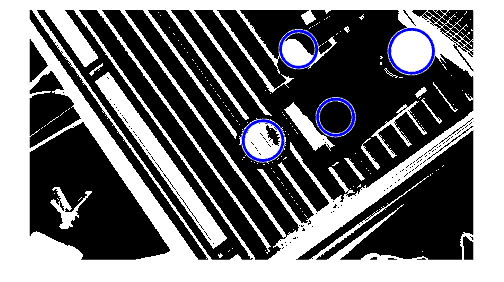

centersStrong5 = centers(1,:); 
radiiStrong5 = radii(1);
metricStrong5 = metric(1);

viscircles(centers, radii,'EdgeColor','b');